# Signal Operations

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the signal $x(t)$ used in Example 1.3:


$$x(t)=\left\{\begin{array}{c r} 2,& -1\le t<2\\ 1,& 2\le t<3\\ -0.5,& 3\le t\le 6\end{array}\right.$$


Express this signal using an anonymous function. Graph it in the time interval $-10\le t\le 10$.

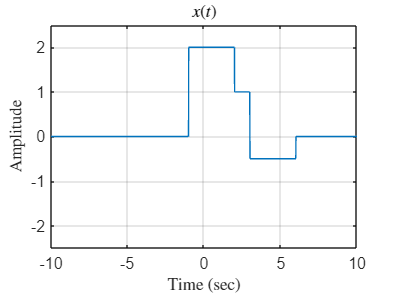

x = @(t) 2*((t>=-1)&(t<2))+...
         1*((t>=2)&(t<3))-...
         0.5*((t>3)&(t<=6));
t = [-10:0.01:10];
set(0,'defaultTextInterpreter','latex');
plot(t,x(t)); grid;      % Remember that x is a function
axis([-10,10,-2.5,2.5]); % Adjust axis limits
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x(t)$');

Generate and graph the signal $g_{1}(t)=x(2t-5)$ in the time interval $-10\le t\le 10$.

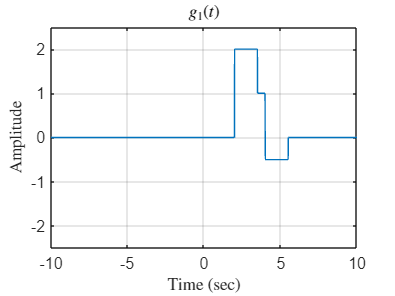

g1 = x(2*t-5);           % g1 is a vector
plot(t,g1); grid;
axis([-10,10,-2.5,2.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$g_{1}(t)$');

Generate and graph the signal $g_{2}(t)=x(-0.5t+2)$ in the time interval $-10\le t\le 10$.

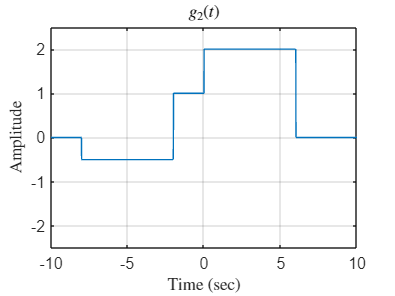

% Let's make g2 another anonymous function
g2 = @(t) x(-0.5*t+2);
plot(t,g2(t)); grid;
axis([-10,10,-2.5,2.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$g_{2}(t)$');

Compute and graph the sum $g_{3}(t)=2g_{1}(t)+g_{2}(t)$ in the time interval $-10\le t\le 10$.

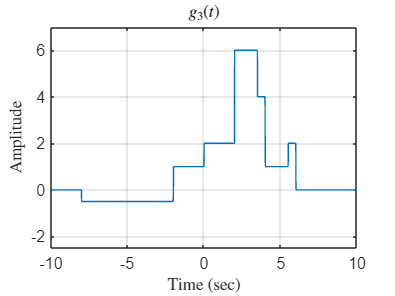

g3 = 2*g1+g2(t);  % Remember: g1 is a vector and g2 is a function
plot(t,g3); grid;
axis([-10,10,-2.5,7]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$g_{3}(t)$');

Compute and graph the product $g_{4}(t)=g_{1}(t) g_{2}(t)$ in the time interval $-10\le t\le 10$.

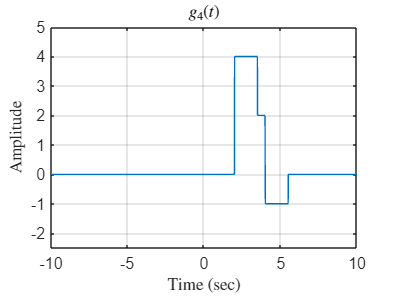

g4 = g1.*g2(t);  % Element by element multiplication
plot(t,g4); grid;
axis([-10,10,-2.5,5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$g_{4}(t)$');

Find even and odd components $x_{e}(t)$ and $x_{o}(t)$ of the signal $x(t)$, and graph them in the time interval $-12\le t\le 12$.  Recall that

        $x_{e}(t)=\frac{x(t)+x(-t)}{2}$                    (1.70)

        $x_{o}(t)=\frac{x(t)-x(-t)}{2}$                    (1.71)

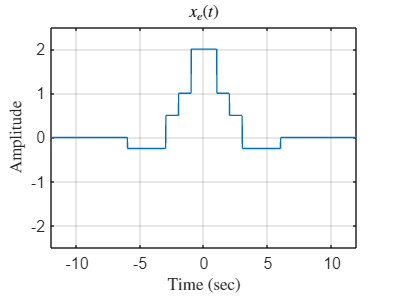

xe = @(t) 0.5*(x(t)+x(-t));  % Function for even component
xo = @(t) 0.5*(x(t)-x(-t));  % Function for odd component 
t = [-12:0.01:12];
plot(t,xe(t)); grid;
axis([-12,12,-2.5,2.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{e}(t)$');

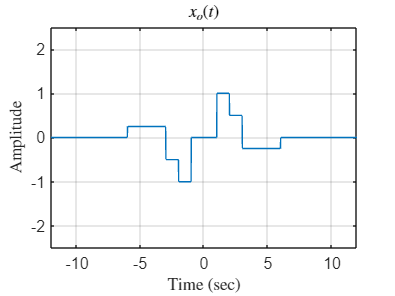

plot(t,xo(t)); grid;
axis([-12,12,-2.5,2.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{o}(t)$');

Check and make sure the components $x_{e}(t)$ and $x_{o}(t)$ add up to the original signal $x(t)$.

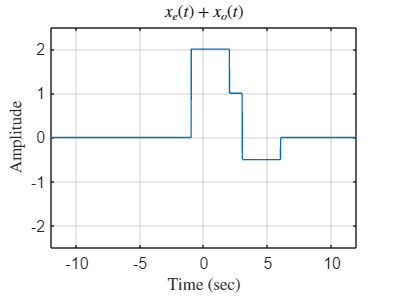

plot(t,xe(t)+xo(t)); grid
axis([-12,12,-2.5,2.5]);
xlabel('Time (sec)');
ylabel('Amplitude');
title('$x_{e}(t)+x_{o}(t)$');

set(0,'defaultTextInterpreter','none');